clear all
s=tf('s')


s =
 
  s
 
Continuous-time transfer function.



G=(s+1)/((s+2)*(s+3)*(s+4))


G =
 
           s + 1
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.




z=tf('z',0.1)


z =
 
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Gz = 0.0017*((z+1)^2*(z-0.9048))/((z-0.7408)*(z-0.6703)*(z-0.8187))


Gz =
 
  0.0017 z^3 + 0.001862 z^2 - 0.001376 z - 0.001538
  -------------------------------------------------
          z^3 - 2.23 z^2 + 1.652 z - 0.4065
 
Sample time: 0.1 seconds
Discrete-time transfer function.



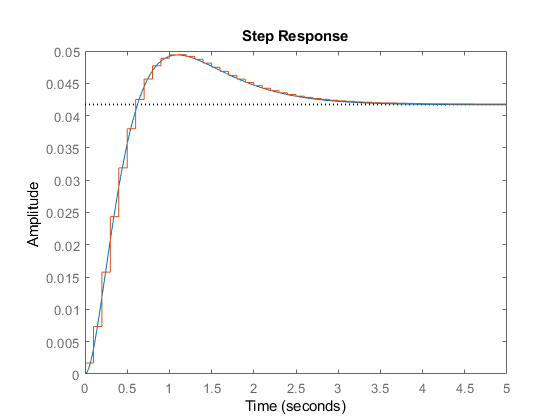


step(G,Gz)


wn=2

wn = 2

zeta=0.9

zeta = 0.9000

T=0.1

T = 0.1000

M=exp(-zeta*wn*T)

M = 0.8353

Phi = wn*sqrt(1-zeta^2)*T

Phi = 0.0872


Gz2 = 1/(z^2-2*M*cos(Phi)*z+M^2)


Gz2 =
 
            1
  ----------------------
  z^2 - 1.664 z + 0.6977
 
Sample time: 0.1 seconds
Discrete-time transfer function.



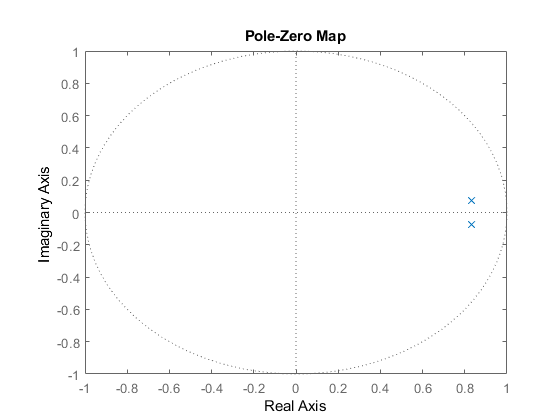

pzmap(Gz2)

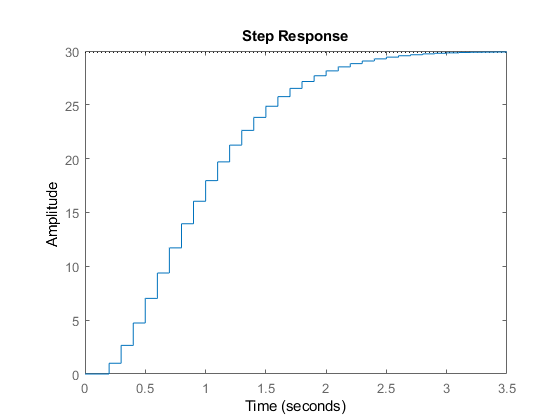

step(Gz2)



wn=24.64

wn = 24.6400

zeta=0.04

zeta = 0.0400

Gaux = 1/(s^2+2*wn*zeta*s+wn^2)


Gaux =
 
            1
  ---------------------
  s^2 + 1.971 s + 607.1
 
Continuous-time transfer function.



T=0.1

T = 0.1000

M=exp(-zeta*wn*T)

M = 0.9061

Phi = wn*sqrt(1-zeta^2)*T

Phi = 2.4620

Gz3 = 1/(z^2-2*M*cos(Phi)*z+M^2)


Gz3 =
 
            1
  ---------------------
  z^2 + 1.41 z + 0.8211
 
Sample time: 0.1 seconds
Discrete-time transfer function.



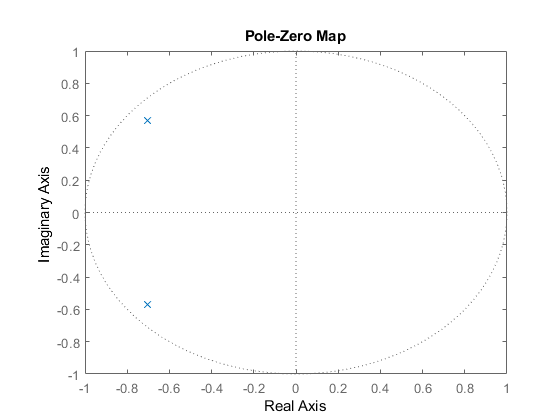

pzmap(Gz3)

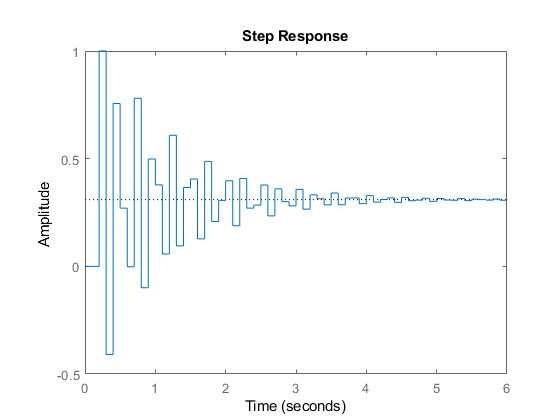

step(Gz3)